**Cumulative distribution function**

[https://uk.mathworks.com/help/stats/cdfplot.html?searchHighlight=cdfplot&s_tid=srchtitle](https://uk.mathworks.com/help/stats/cdfplot.html?searchHighlight=cdfplot&s_tid=srchtitle)

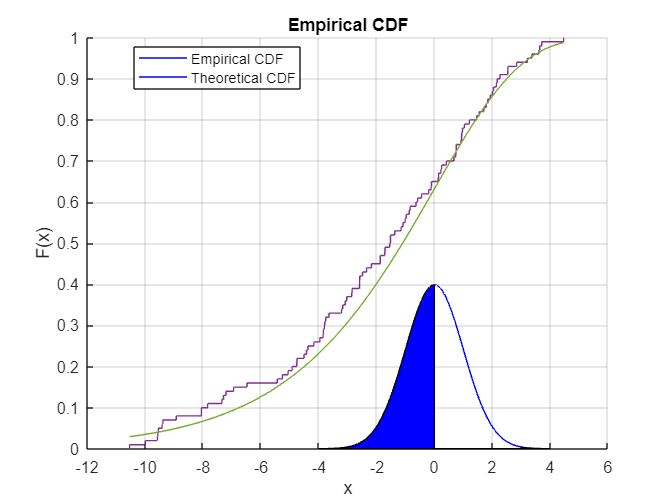

rng('default')  % For reproducibility
y = evrnd(0,3,100,1);

cdfplot(y)
hold on
x = linspace(min(y),max(y));
plot(x,evcdf(x,0,3))
legend('Empirical CDF','Theoretical CDF','Location','best')
hold off

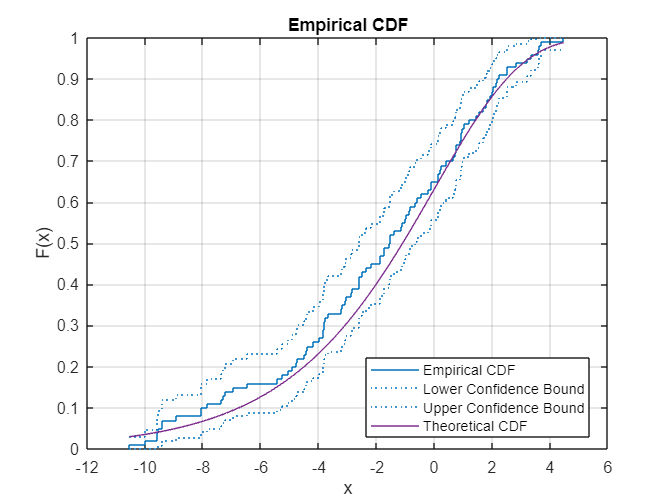

ecdf(y,'Bounds','on')
hold on
plot(x,evcdf(x,0,3))
grid on
title('Empirical CDF')
legend('Empirical CDF','Lower Confidence Bound','Upper Confidence Bound','Theoretical CDF','Location','best')
hold off

**Stairs function**

[https://uk.mathworks.com/help/matlab/ref/stairs.html](https://uk.mathworks.com/help/matlab/ref/stairs.html)

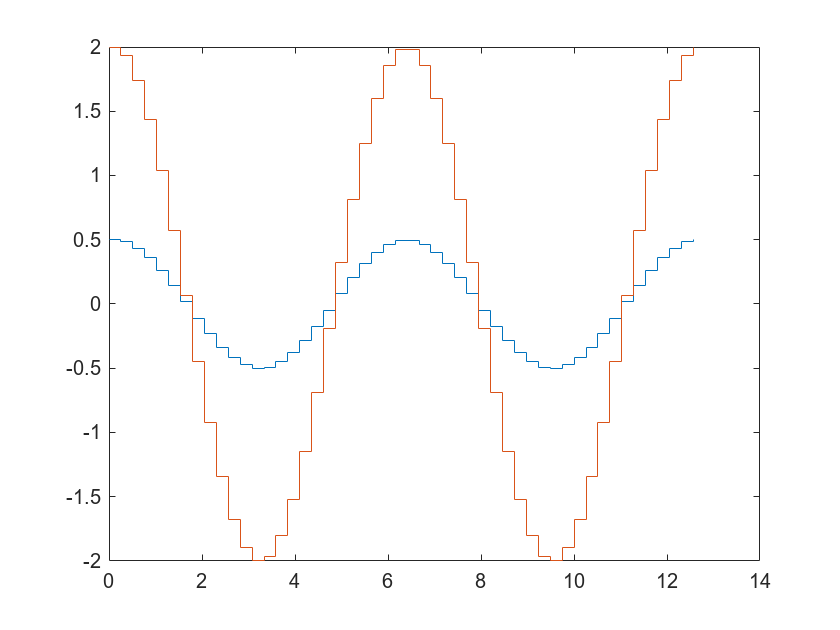

X = linspace(0,4*pi,50)';
Y = [0.5*cos(X), 2*cos(X)];

stairs(X,Y)

**Histogram **

[https://uk.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html](https://uk.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html)

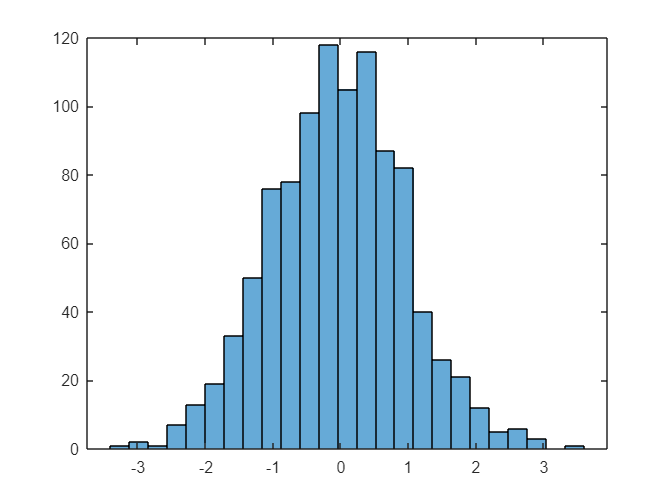

h =   Histogram with properties:

             Data: [1000×1 double]
           Values: [1 2 1 7 13 19 33 50 76 78 98 118 105 116 87 82 40 26 21 12 5 6 3 0 1]
          NumBins: 25
         BinEdges: [-3.4000 -3.1200 -2.8400 -2.5600 -2.2800 -2 -1.7200 -1.4400 -1.1600 -0.8800 -0.6000 -0.3200 -0.0400 0.2400 0.5200 0.8000 1.0800 1.3600 1.6400 1.9200 2.2000 2.4800 2.7600 3.0400 3.3200 3.6000]
         BinWidth: 0.2800
        BinLimits: [-3.4000 3.6000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


x = randn(1000,1);
nbins = 25;
h = histogram(x,nbins)

**Histogram bin counts**

[https://uk.mathworks.com/help/matlab/ref/histcounts.html](https://uk.mathworks.com/help/matlab/ref/histcounts.html)

X = [2 3 5 7 11 13 17 19 23 29];
numBins = 6;
[N,edges] = histcounts(X,numBins)

N =      2     2     2     2     1     1


edges =          0    4.9000    9.8000   14.7000   19.6000   24.5000   29.4000


**Creating distributions**

[https://uk.mathworks.com/help/stats/makedist.html](https://uk.mathworks.com/help/stats/makedist.html)

pd = makedist('Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


methods(pd)

Methods for class prob.NormalDistribution:

cdf        pdf        
gather     plot       
icdf       proflik    
iqr        random     
mean       std        
median     truncate   
negloglik  var        
paramci    



interQuartileRange = iqr(pd)

interQuartileRange = 1.3490

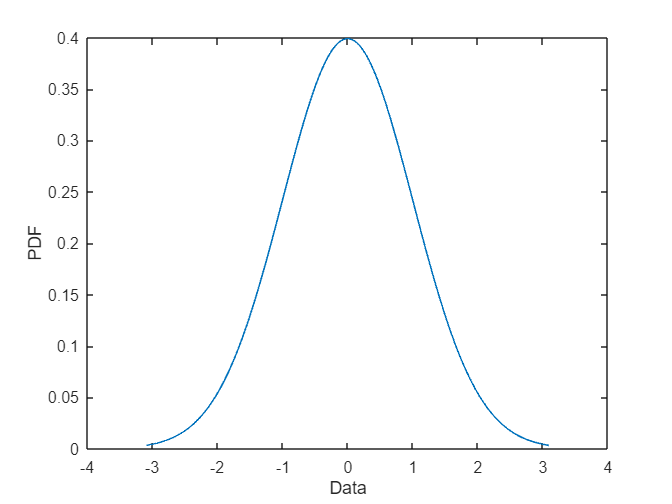

pd.plot

**Inverse cumulative distribution function**

[https://uk.mathworks.com/help/stats/prob.normaldistribution.icdf.html?searchHighlight=%20icdf&s_tid=srchtitle](https://uk.mathworks.com/help/stats/prob.normaldistribution.icdf.html?searchHighlight=%20icdf&s_tid=srchtitle)

p = [0.1,0.25,0.5,0.75,0.9];
mu = 1;
sigma = 5;
y = icdf('Normal',p,mu,sigma)

y =    -5.4078   -2.3724    1.0000    4.3724    7.4078


pd = makedist('Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1



% Set 5% significance level, 2.5% on either side
x = icdf(pd,[.025,.975])

x =    -1.9600    1.9600


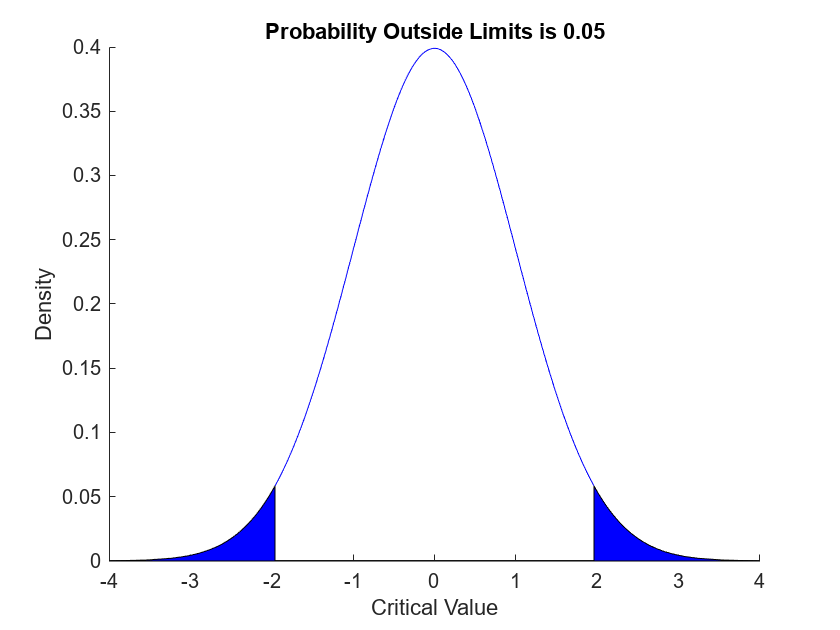

p = 0.0500

p = normspec(x,0,1,'outside')